clc
clear all
close all

[m,g,c,Rb,Lb,p0] = getvaluesT3(20102977);

% massa do objeto metálico
m

m = 1.5000

% aceleração da gravidade
g

g = 9.7900

% constante eletromagnética da bobina
c

c = 0.3000

% resistência elétrica da bobina
Rb

Rb = 3

% indutância elétrica da bobina
Lb

Lb = 0.4000

% distância nominal de levitação
p0

p0 = 0.0400

s = tf('s');
i0 = sqrt((m*g*p0)/c)

i0 = 1.3993

A = [ 0                 0                   1
      0                 -Rb/Lb              0
      (c/m)*(i0/p0)^2   (2*c/m)*(i0/p0)     0 ]

A =          0         0    1.0000
         0   -7.5000         0
  244.7500   13.9929         0


B = [ 0
      1/Lb
      0 ]

B =          0
    2.5000
         0


C = [ 1 0 0 ]

C =      1     0     0


D = 0

D = 0

x0 = [ 0.005
       0
       0 ]

x0 =     0.0050
         0
         0


G = minreal(C*inv(s*eye(3)-A)*B+D)


G =
 
              34.98
  ------------------------------
  s^3 + 7.5 s^2 - 244.8 s - 1836
 
Continuous-time transfer function.


eig(A)

ans =    15.6445
  -15.6445
   -7.5000


pole(G)

ans =    15.6445
  -15.6445
   -7.5000


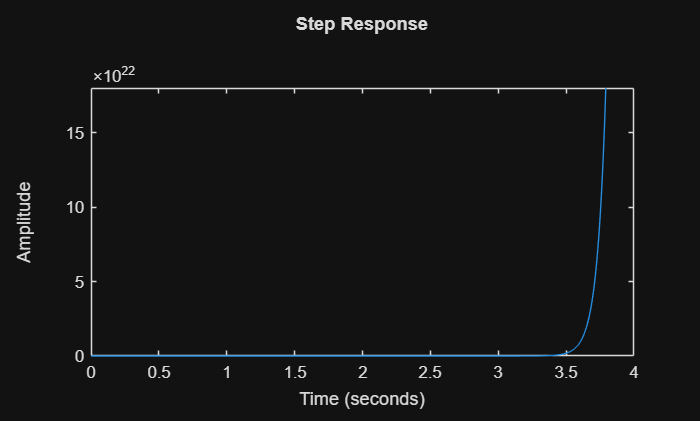

sys = ss(A,B,C,D);
step(sys);

syms x;
vpa(x * eye(3) - A)

$$ans = \left(\begin{array}{ccc} x & 0 & -1.0\\ 0 & x+7.5 & 0\\ -244.75 & -13.992855319769442967410987404346 & x \end{array}\right)$$

det(vpa(x * eye(3) - A))

$$ans = 1.0\,x^{3}+7.5\,x^{2}-244.75\,x-1835.625$$

vpa(root(det(vpa(x * eye(3) - A)), x))

$$ans = \left(\begin{array}{c} -7.5\\ 15.644487847162015677360312085399\\ -15.644487847162015677360312085399 \end{array}\right)$$

## Controlabilidade e Observabilidade

Ctrl = [B A*B A*A*B]

Ctrl =          0         0   34.9821
    2.5000  -18.7500  140.6250
         0   34.9821 -262.3660


det(Ctrl)

ans = 3.0594e+03

Obs = [ C
        C*A
        C*A*A ]

Obs =     1.0000         0         0
         0         0    1.0000
  244.7500   13.9929         0


det(Obs)

ans = -13.9929